导入数据

global  omiga HH W ig
s1=load("20201016_01_01");
s2=load("20201016_01_02");
s3=load("20201016_01_03");
s4=load("20201016_01_04");
s5=load("20201016_01_05");
s6=load("20201016_01_06");
s7=load("20201016_01_07");
s8=load("20201016_01_08");
s9=load("20201016_01_09");
s10=load("20201016_01_10");
s11=load("20201016_05_01");
s12=load("20201016_05_02");
s13=load("20201016_05_03");
s14=load("20201016_05_04");
s15=load("20201016_05_05");
s16=load("20201016_05_06");
s17=load("20201016_05_07");
s18=load("20201016_05_08");
s19=load("20201016_05_09");
s20=load("20201016_05_10");
S=[s1.MAT_001_FRF_Channel_8(:,2) s2.MAT_001_FRF_Channel_8(:,2) s3.MAT_001_FRF_Channel_8(:,2)...
    s4.MAT_001_FRF_Channel_8(:,2) s5.MAT_001_FRF_Channel_8(:,2) s6.MAT_001_FRF_Channel_8(:,2)...
    s7.MAT_001_FRF_Channel_8(:,2) s8.MAT_001_FRF_Channel_8(:,2) s9.MAT_001_FRF_Channel_8(:,2)...
    s10.MAT_001_FRF_Channel_8(:,2) s11.MAT_001_FRF_Channel_8(:,2) s12.MAT_001_FRF_Channel_8(:,2)...
    s13.MAT_001_FRF_Channel_8(:,2) s14.MAT_001_FRF_Channel_8(:,2) s15.MAT_001_FRF_Channel_8(:,2)...
    s16.MAT_001_FRF_Channel_8(:,2) s17.MAT_001_FRF_Channel_8(:,2) s18.MAT_001_FRF_Channel_8(:,2)...
    s19.MAT_001_FRF_Channel_8(:,2) s20.MAT_001_FRF_Channel_8(:,2)];

单模态识别;差分法（粘性阻尼模型）

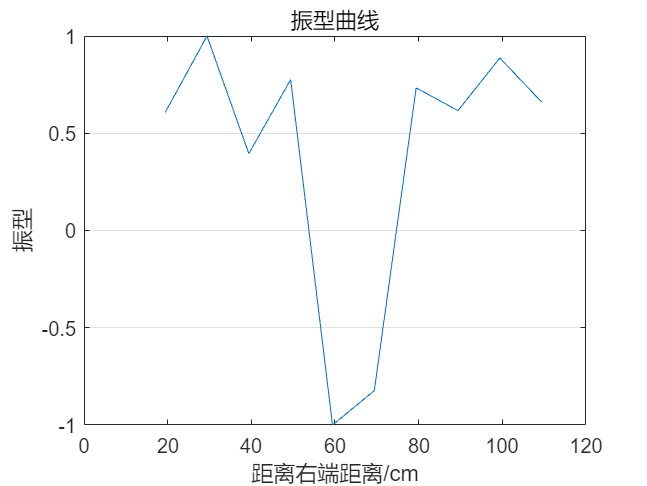

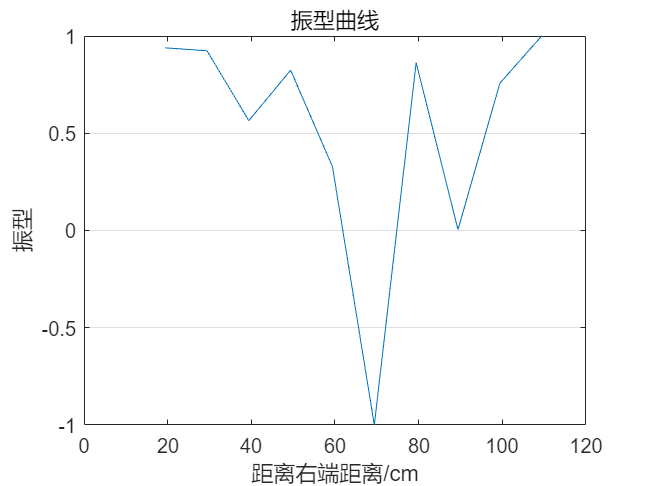

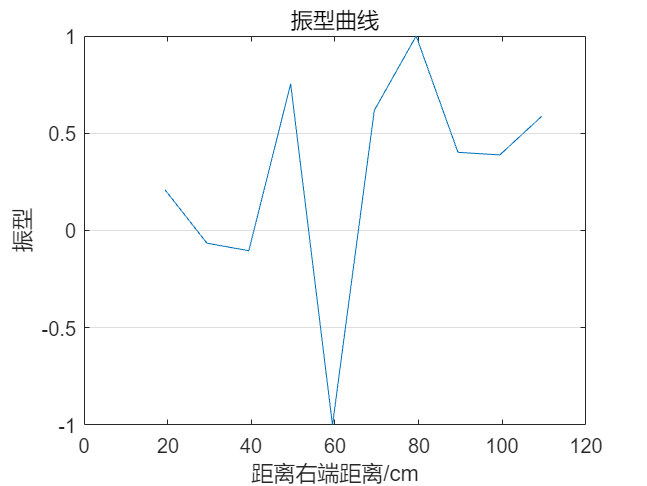

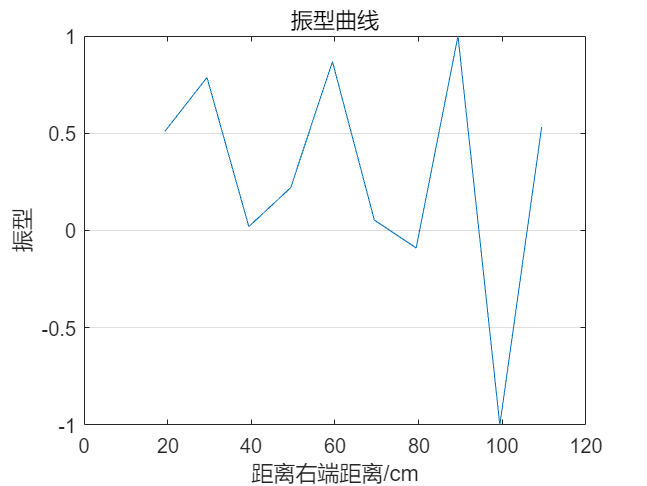

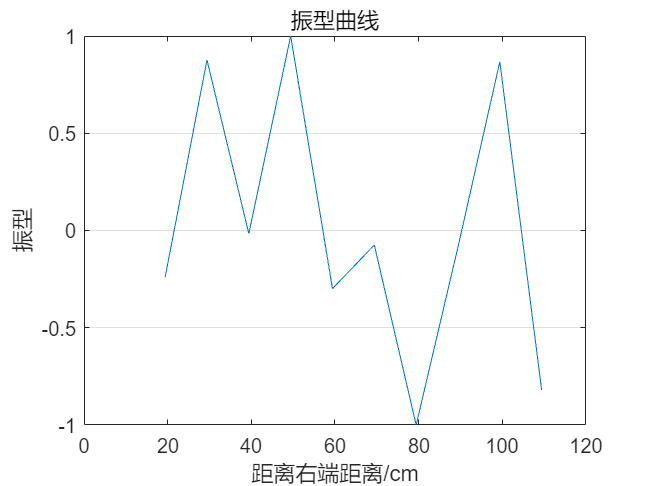

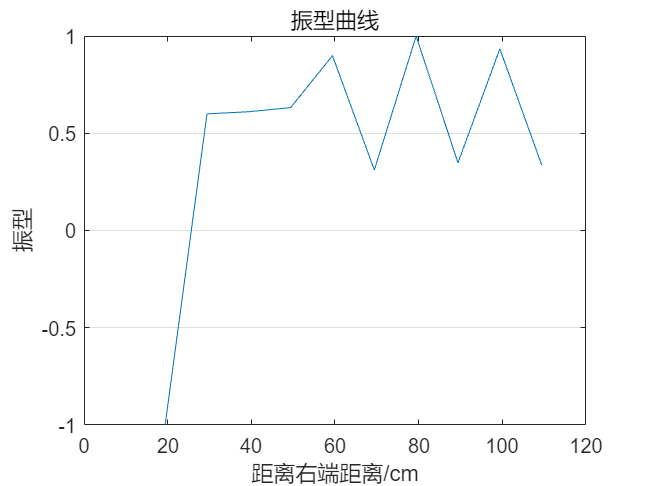

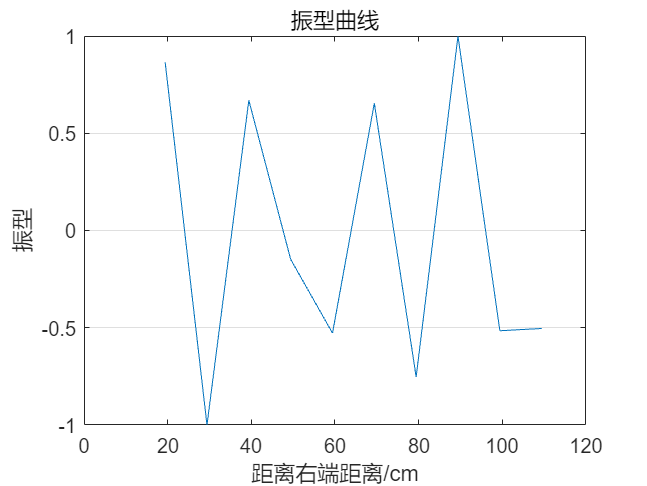

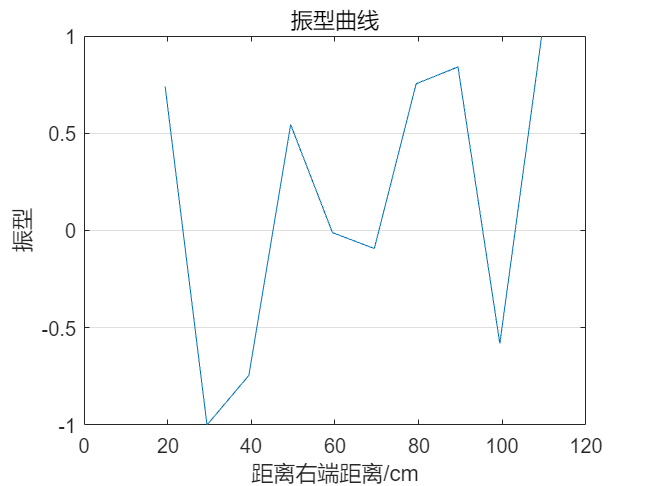

omiga=2*pi*s1.MAT_001_FRF_Channel_8(:,1);
s=[10 27 53.5 88 131.5 184 246 316 394.5 482];
ss=s/0.5+1;
y=[19.4 29.4 39.4 49.4 59.4 69.4 79.4 89.4 99.4 109.4];
ri=zeros(1,10);
for kk=1:10
for m=1:10
    figure(10+m);
    for n=1:6
    rr(n)=-abs(S(ss(kk)-3+n-1,m)*S(ss(kk)-3+n,m)*0.5/(S(ss(kk)-3+n-1,m)*omiga(ss(kk)-3+n).^2-S(ss(kk)-3+n,m)*omiga(ss(kk)-3+n-1).^2));
    omigamdi(n)=real((S(ss(kk)-3+n,m)/(-omiga(ss(kk)-3+n))-S(ss(kk)-3+n-1,m)/(-omiga(ss(kk)-3+n-1)))*omiga(ss(kk)-3+n).^2*omiga(ss(kk)-3+n-1).^2/(S(ss(kk)-3+n-1,m)*omiga(ss(kk)-3+n).^2-S(ss(kk)-3+n,m)*omiga(ss(kk)-3+n-1).^2));
    zetamdi(n)=imag((S(ss(kk)-3+n,m)/(-omiga(ss(kk)-3+n))-S(ss(kk)-3+n-1,m)/(-omiga(ss(kk)-3+n-1)))*omiga(ss(kk)-3+n).^2*omiga(ss(kk)-3+n-1).^2/(S(ss(kk)-3+n-1,m)*omiga(ss(kk)-3+n).^2-S(ss(kk)-3+n,m)*omiga(ss(kk)-3+n-1).^2));
    plot(omiga(ss(kk)-3+n-1)/pi/2,20*log(abs(S(ss(kk)-3+n-1,m))),'*r','markersize',10);
    hold on;
    end
    kesimdi=zetamdi/omigamdi;
    rrr(kk,m)=mean(rr);
    omigamd(kk,m)=mean(abs(omigamdi));%复模态阻尼固有频率矩阵rad/s
    zetamd(kk,m)=mean(abs(zetamdi));%复模态阻尼衰减系数矩阵
    kesimd(kk,m)=mean(kesimdi);%复模态阻尼比矩阵
end
omigam(kk)=mean(omigamd(kk,:));%复模态阻尼固有频率10条曲线平均值rad/s
zetam(kk)=mean(zetamd(kk,:));%复模态阻尼衰减系数10条曲线平均值
kesim(kk)=mean(kesimd(kk,:));%复模态阻尼比10条曲线平均值
r=mapminmax(rrr(kk,:));%主导模态的复模态振型归一化
figure(kk);
plot(y,r);
xlabel("距离右端距离/cm");
ylabel("振型");
title("振型曲线");
set(gca,'XGrid','off','YGrid','on');
hold on;
end

for k=1:10
    figure(10+k);
    plot(s1.MAT_001_FRF_Channel_8(:,1),20*log(abs(S(:,k))),'g-');
    xlabel("采样频率f/Hz");
    ylabel("幅频H（f）/dB");
    legend('差分法所用数据','原始数据');
    hold on;
end
xlswrite('omigamd.xlsx',omigamd'/2/pi);%单位Hz
xlswrite('zetamd.xlsx',zetamd);
xlswrite('kesimd.xlsx',kesimd);

单模态识别拟合

for p=1:10
    figure(10+p);
    for q=1:10
        for R=1:20
            H(ss(q)-11+R)=-rrr(q,p)*(omiga(ss(q)-11+R)).^2/(omigamd(q,p)-omiga(ss(q)-11+R)+zetamd(q,p)*1j);
        end
        plot(omiga(ss(q)-10:ss(q)+9)/2/pi,20*log(abs(H(ss(q)-10:ss(q)+9))));
        hold on;
    end
end

多模态识别：非线性加权最小二乘法（粘性比例阻尼系统）直接偏导数法寻优

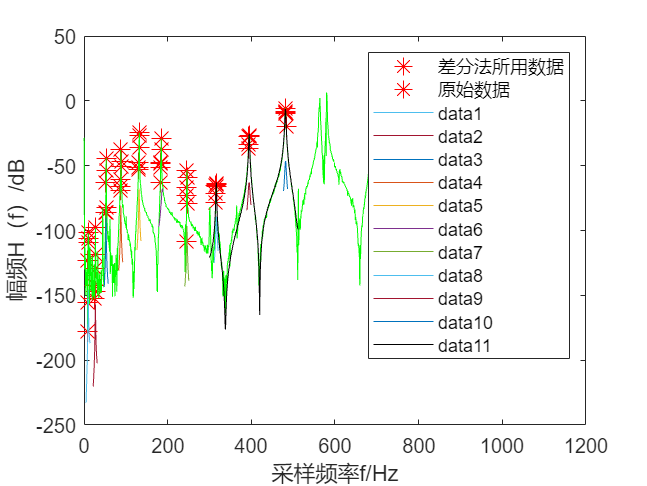

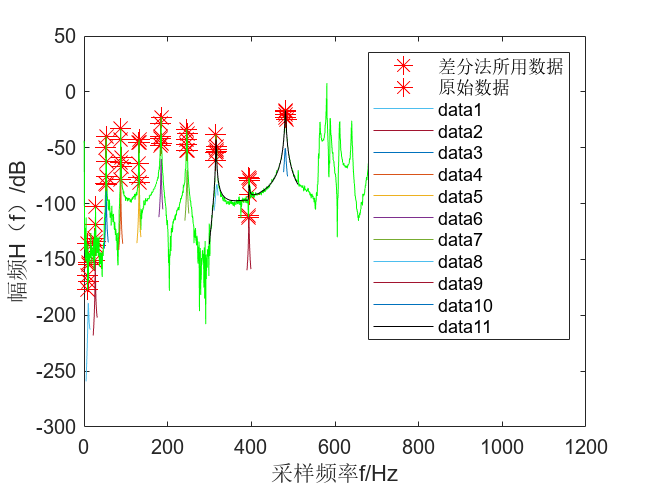

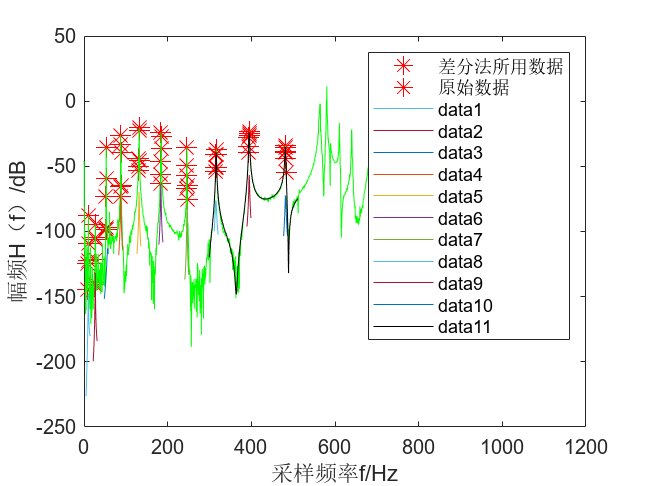

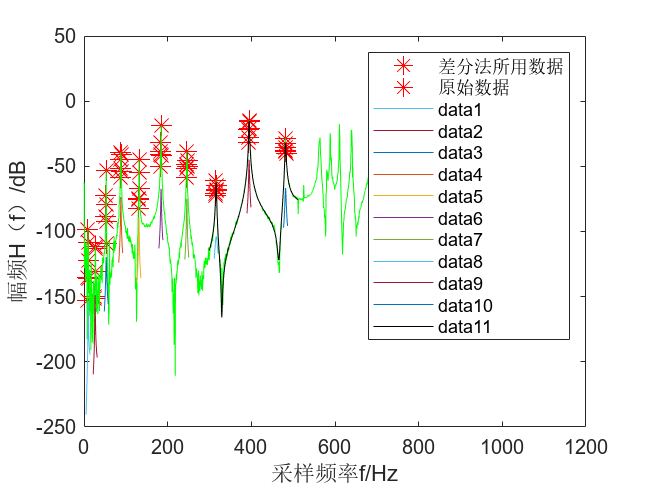

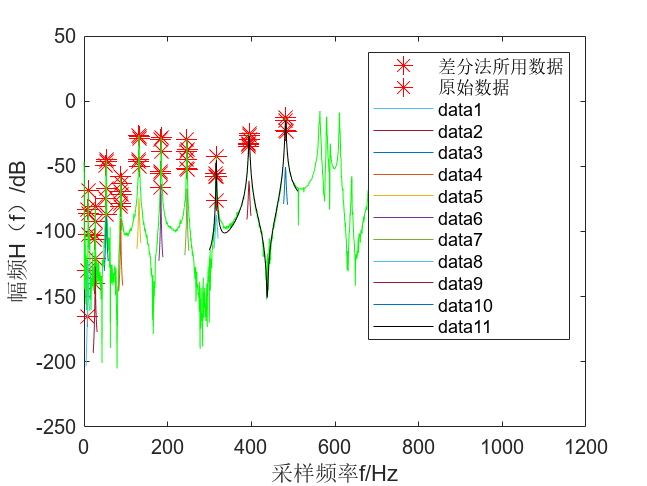

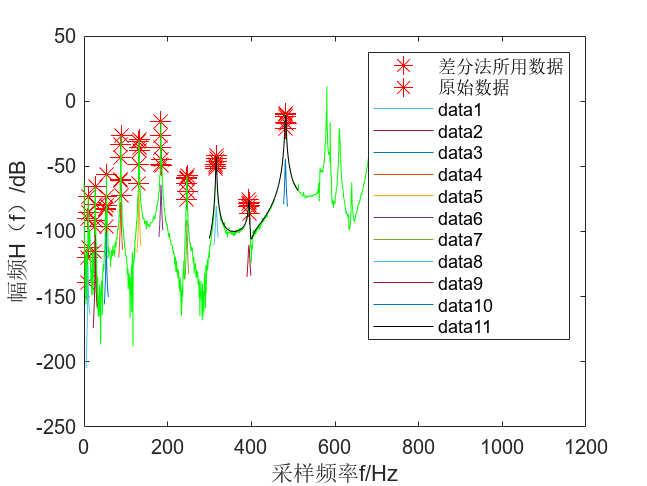

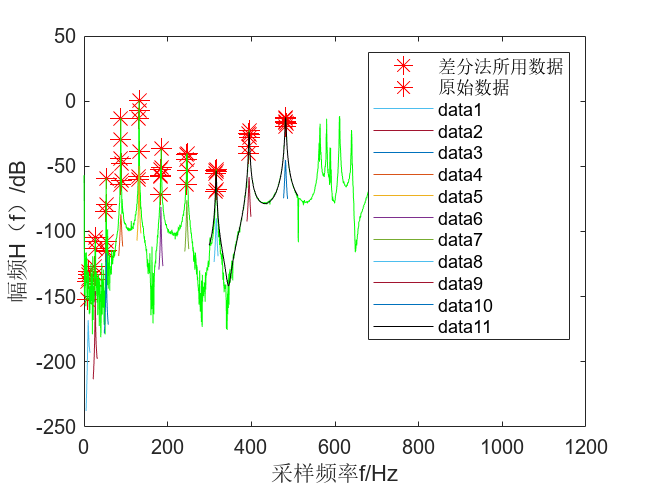

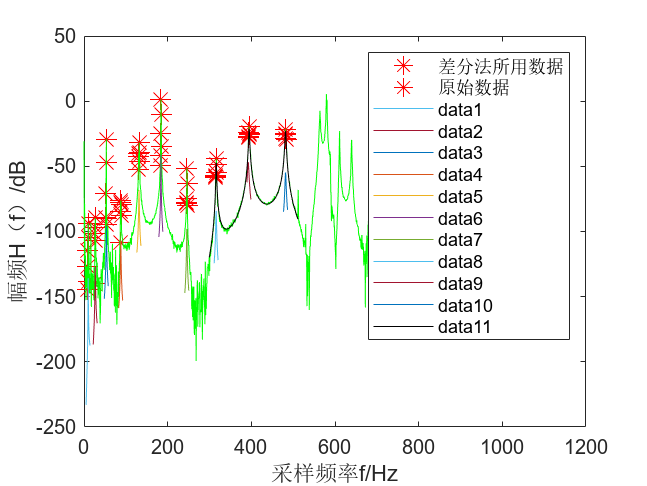


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 3.954444 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 7.180528 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 6.535284 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 6.272873 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 10.568394 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 5.126811 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 5.929308 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 6.785542 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 6.027977 秒。



Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


历时 9.875195 秒。


% for k=1:512%线性参数识别
%     E(k,1)=1;E(k,2)=0;E(k,23)=1;E(k,24)=0;
%     F(k,1)=0;F(k,2)=1;F(k,23)=0;F(k,24)=1;
% end
% for k=1:10
%     for kk=1:512
%     E(kk,2*k+1)=-omiga(kk).^2*((zeta(k)/(zeta(k).^2+(omiga(kk)-omigam(k)).^2))+(zeta(k)/(zeta(k).^2+(omiga(kk)+omigam(k)).^2)));
%     E(kk,2*k+2)=-omiga(kk).^2*(((omiga(kk)-omigam(k))/(zeta(k).^2+(omiga(kk)-omigam(k)).^2))+...
%         ((omiga(kk)+omigam(k))/(zeta(k).^2+(omiga(kk)+omigam(k)).^2)));
%     F(kk,2*k+1)=-omiga(kk).^2*((-(omiga(kk)-omigam(k))/(zeta(k).^2+(omiga(kk)-omigam(k)).^2))+...
%         ((omiga(kk)+omigam(k))/(zeta(k).^2+(omiga(kk)+omigam(k)).^2)));
%     F(kk,2*k+2)=-omiga(kk).^2*((zeta(k)/(zeta(k).^2+(omiga(kk)-omigam(k)).^2))-(zeta(k)/(zeta(k).^2+(omiga(kk)+omigam(k)).^2)));
%     end
% end
% P=inv(E*E'+F*F')*(E'*real(S(1:512,1))+F'*imag(S(1:512,1)));%P=[YR YI U1 V1 U2 V2 ...Um Vm ZR ZI];m=10
%     
for k=1:10
    tic;
HH=S(600:1024,k);
for j=1:3%建立模态初始参数向量
    l=4*(j-1);
    x0(l+1:l+4)=[-s(7+j)*2*pi*kesim(7+j),s(7+j)*2*pi*sqrt(1-kesim(7+j).^2),1,1];
end
W=(abs(HH)./max(abs(HH))).^0.2;%建立权向量
ig=1;
x=lsqnonlin('fun83',x0);%非线性加权最小二乘法估计复模态参数
for j=1:3
    l=4*(j-1);
    c=x(l+1)+i*x(l+2); 
    d=x(l+3)+i*x(l+4);
    F(k,j)=abs(c)/2/pi;%模态频率
    D(k,j)=-real(c)/abs(c);%阻尼比
end
ig=0;
H1=fun83(x);%计算拟合频响函数
figure(10+k);
plot(omiga(600:1024)/2/pi,20*log(abs(H1(:,1))),'k-');
hold on;
toc
t(k)=toc;
end